# setup

% check if run from correct path:
[~, lastdir, ~] = fileparts(pwd);
if (~strcmp(lastdir, "AE4301P")) || (exist("./F16Sim_rev/") ~= 7)
    error(strcat("Please run ",...
                 mfilename,...
                 " from the root directory of this project"...
                 ))
end

run setup.m

setup.m: Setting up matlab-path


## IMPORTANT: Do you want to see plots on-screen and in the Live Script in-line output? (they are saved anyway in the Outputs directory)

% show plots on-screen?
show_plots = "on";

## generate flight conditions

new_section("main: generate FlightCondition.mat file")




    main: generate FlightCondition.mat file
    ---------------------------------------



run gen_fc.m

gen_fc: Generating 8 flight conditions to be written to FlightConditions.mat...done


## Chapter 4.0 Linearization

new_section("main: Running Linearization tasks of Chapter 4.0")




    main: Running Linearization tasks of Chapter 4.0
    ------------------------------------------------




run Ch4_0_TrimLin.m

gen_fc: Generating 8 flight conditions to be written to FlightConditions.mat...done
trim-lin: Load FlightConditions.mat file...
trim-lin: trimming and linearizing condition Std_LoFi_full
trim-lin: trimming and linearizing condition Std_HiFi_full
trim-lin: trimming and linearizing condition Accel_LoFi_full
trim-lin: trimming and linearizing condition Accel_HiFi_full
trim-lin: trimming and linearizing condition Std_LoFi_5DoF
trim-lin: reducing condition Std_LoFi_5DoF
trim-lin: trimming and linearizing condition Std_LoFi_4DoF
trim-lin: reducing condition Std_LoFi_4DoF
trim-lin: trimming and linearizing condition Std_LoFi_2DoF
trim-lin: reducing condition Std_LoFi_2DoF
trim-lin: trimming and linearizing condition GS_HiFi_full
trim-lin: trimming and linearizing condition GS_LoFi_5DoF
trim-lin: reducing condition GS_LoFi_5DoF
trim-lin: trimming and linearizing condition GS_LoFi_2DoF
trim-lin: reducing condition GS_LoFi_2DoF


cost_residuals_tab = 6×1 table
                    Cost_residuals
                    ______________

    Cruise LoFi       5.8596e-28  
    Cruise HiFi       1.2084e-06  
    Accel LoFi        2.2909e-29  
    Accel HiFi        7.1856e-06  
    Landing LoFi      4.7464e-30  
    Landing HiFi      7.8918e-06  


trim_lin: done


VerifyReduction.m: Checking if SS matrices exist...OK
VerifyReduction: The 2 transfer functions below should be the same:

ans =
 
         -254.8 s^3 - 171.8 s^2 - 2.076 s + 1.466e-13
  -----------------------------------------------------------
  s^5 + 21.82 s^4 + 36.34 s^3 + 71.85 s^2 + 0.6948 s + 0.2266
 
Continuous-time transfer function.


ans =
 
         -254.8 s^3 - 171.8 s^2 - 2.076 s + 4.307e-11
  -----------------------------------------------------------
  s^5 + 21.82 s^4 + 36.34 s^3 + 71.85 s^2 + 0.6948 s + 0.2266
 
Continuous-time transfer function.



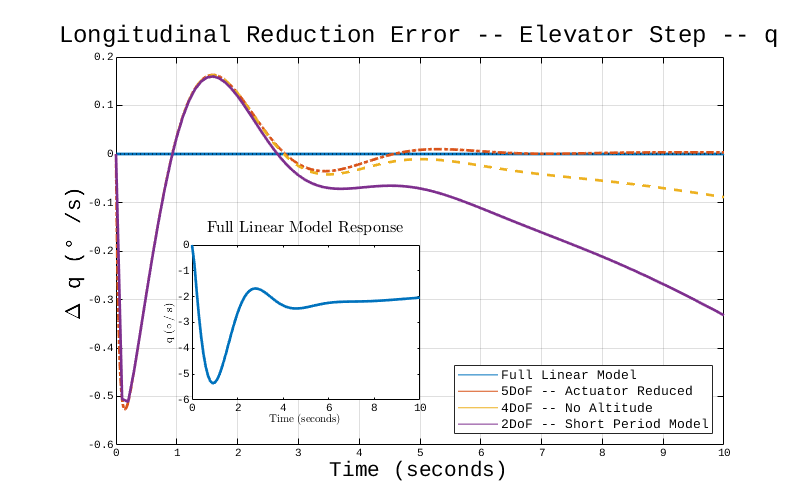

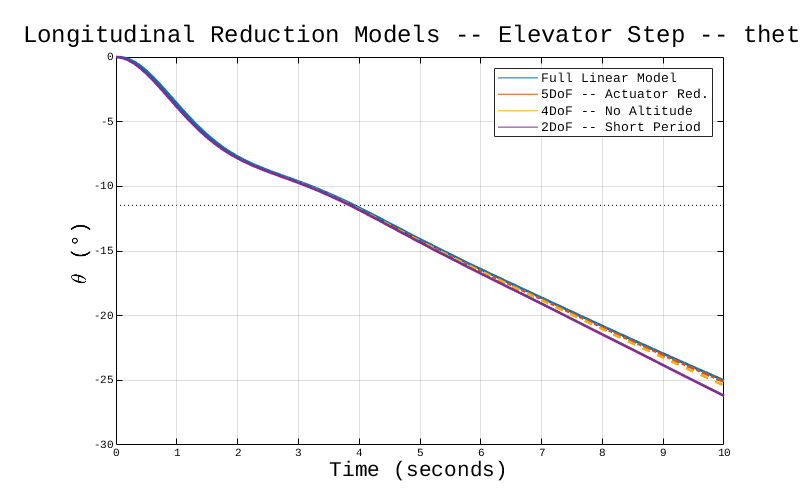

run VerifyReduction.m

## Chapter 4.1 Acclerometer

clearvars -except show_plots fc
close("all")

new_section("main: Running Acclerometer tasks of Chapter 4.1")




    main: Running Acclerometer tasks of Chapter 4.1
    -----------------------------------------------



FindF16Dynamics_noninteractive.m: using Modified LIN_F16Block_an.mdl for linearization

Ch4_1_Accel: Task 4.4 -- a_n depends on v, \alpha, q, \delta_e 



FindF16Dynamics_noninteractive.m: using Modified LIN_F16Block_an.mdl for linearization


FindF16Dynamics_noninteractive.m: using Modified LIN_F16Block_an.mdl for linearization


FindF16Dynamics_noninteractive.m: using Modified LIN_F16Block_an.mdl for linearization


FindF16Dynamics_noninteractive.m: using Modified LIN_F16Block_an.mdl for linearization


FindF16Dynamics_noninteractive.m: using Modified LIN_F16Block_an.mdl for linearization


FindF16Dynamics_noninteractive.m: using Modified LIN_F16Block_an.mdl for linearization


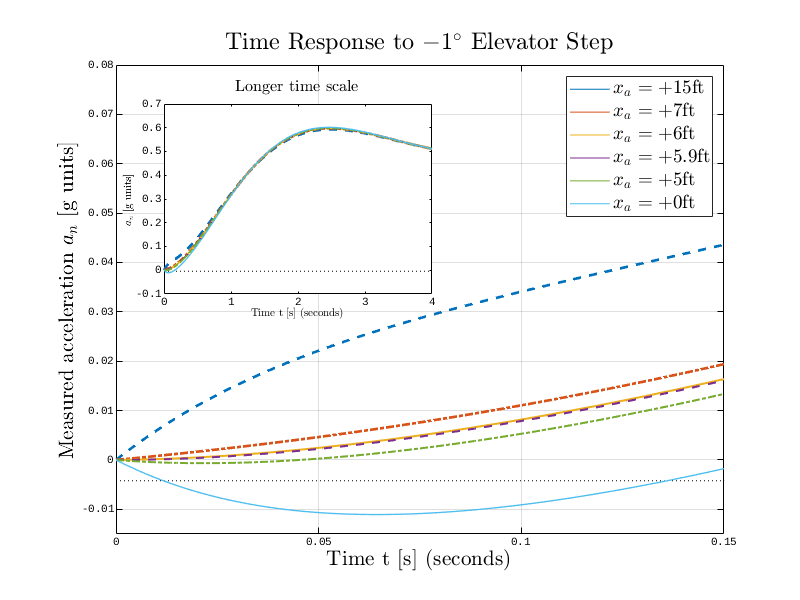

Ch4_1_Accel: Sweeping through x_a (in feet) yields the following OL-zeros:


zeros_el2an_sweep = 6×5 table
           x_a         Zero1              Zero2           Zero3        Zero4   
           ___    _______________    _______________    _________    __________

    15      15    -1.9412-5.5105i    -1.9412+5.5105i    0.0093859    -0.0059183
    7        7    -13.735-9.6727i    -13.735+9.6727i    0.0093878    -0.0059185
    6        6    -283.72+0i         -10.898+0i         0.0093881    -0.0059185
    5.9    5.9     -67142+0i         -10.519+0i         0.0093881    -0.0059185
    5        5     40.673+0i         -8.4873+0i         0.0093883    -0.0059185
    0        0     9.7597+0i         -5.3925+0i         0.0093895    -0.0059186


run Ch4_1_Accel.m

## Chapter 5 Open Loop Characteristics

clearvars -except show_plots fc zeros_el2an_sweep
close("all")

% observe the characteristics in the Command Window output and 6 plots that
% pop up
new_section("main: Running Open Loop tasks of Chapter 5")




    main: Running Open Loop tasks of Chapter 5
    ------------------------------------------



Ch5_OpenLoop: Checking if SS matrices exist...OK
Ch5_OpenLoop: Calculate table of numerical characteristics...OK
Open Loop Characteristics: 


char_tab = 8×5 table
                              NaturalFrequency    DampingRatio    TimeConstant    HalfTime            Pole        
                              ________________    ____________    ____________    ________    ____________________

    Phugoid                       0.046525           0.08882         241.99        167.74     -0.0041324+0.046341i
    Phugoid Conjugate             0.046525           0.08882         241.99        167.74     -0.0041324-0.046341i
    Short Period                    1.8811           0.42925         1.2384       0.85843       -0.80746+1.699i   
    Short Period Conjugate          1.8811           0.42925         1.2384       0.85843       -0.80746-1.699i   
    Spiral                       

Ch5_OpenLoop: making Pole Zero maps...

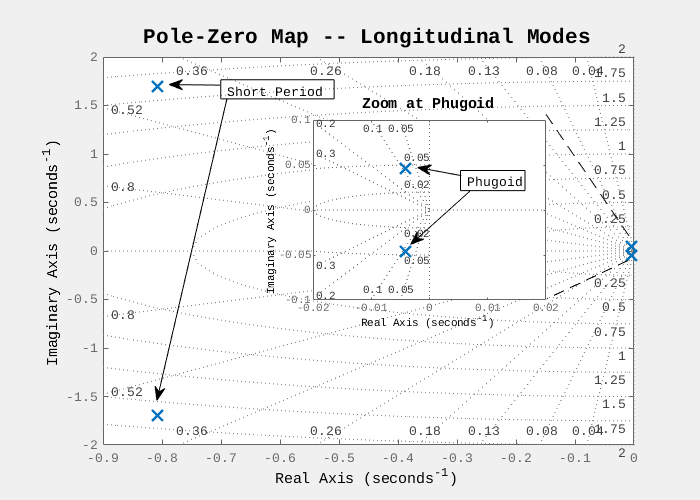

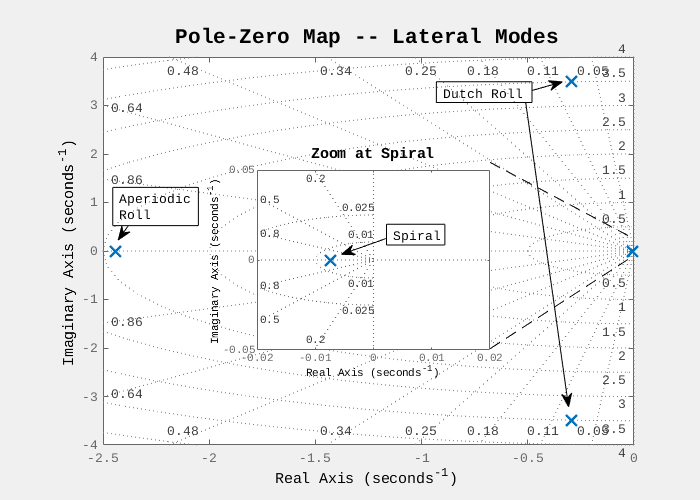

OK
Ch5_OpenLoop: making time domain response plots...

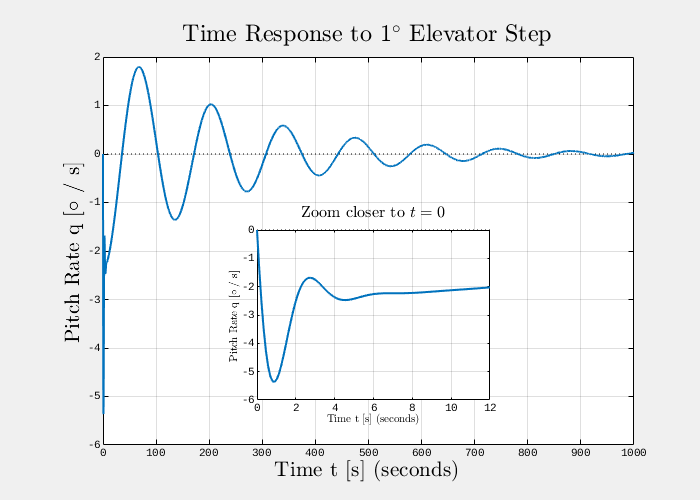

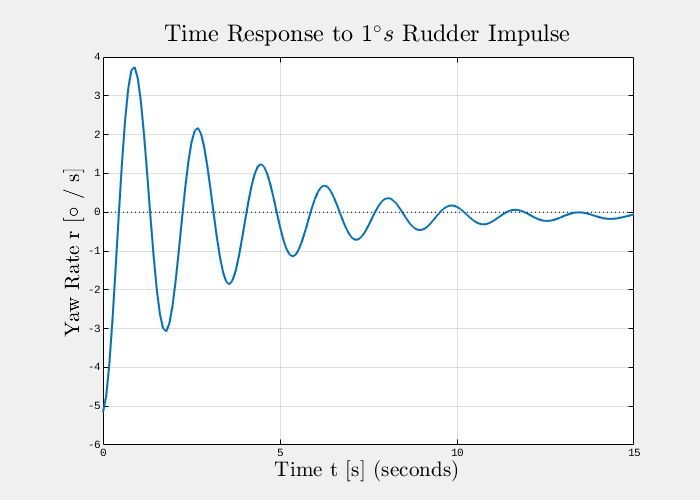

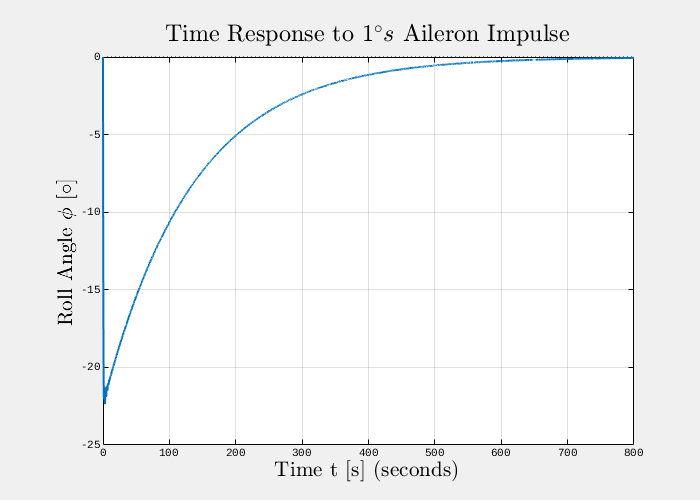

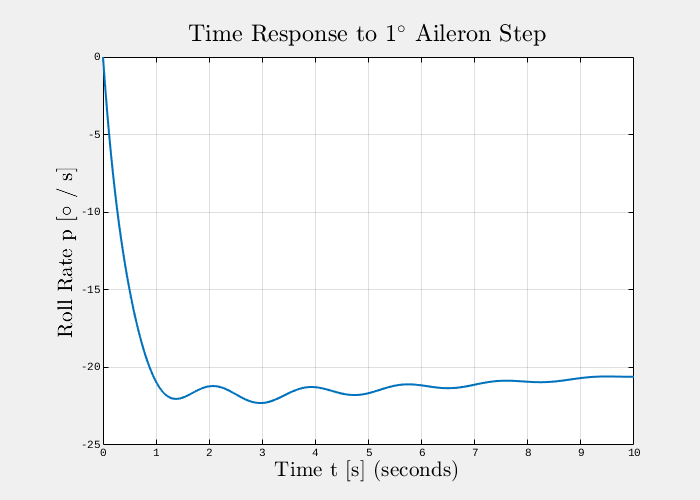

OK
Ch5_OpenLoop: done


run Ch5_OpenLoop.m



% Verify the longitudinal system reduction (5.0, 5.2)
%
% Observe the identical transfer functions in the Command Window output and
% the 2 plots that pop up
new_section("main: Verify the reduction techniques used in Chapter 5 and after")




    main: Verify the reduction techniques used in Chapter 5 and after
    -----------------------------------------------------------------



VerifyReduction.m: Checking if SS matrices exist...OK
VerifyReduction: The 2 transfer functions below should be the same:

ans =
 
         -254.8 s^3 - 171.8 s^2 - 2.076 s + 1.466e-13
  -----------------------------------------------------------
  s^5 + 21.82 s^4 + 36.34 s^3 + 71.85 s^2 + 0.6948 s + 0.2266
 
Continuous-time transfer function.


ans =
 
         -254.8 s^3 - 171.8 s^2 - 2.076 s + 4.307e-11
  -----------------------------------------------------------
  s^5 + 21.82 s^4 + 36.34 s^3 + 71.85 s^2 + 0.6948 s + 0.2266
 
Continuous-time transfer function.



run VerifyReduction.m

## Chapter 6 q command system

new_section("main: q-Command (Chapter 6) Pole Placement and Handling Characteristics")




    main: q-Command (Chapter 6) Pole Placement and Handling Characteristics
    -----------------------------------------------------------------------



Ch6_q_Command: Checking if SS matrices exist...OK
PlacePoles.m: Verify same implementation PLacePoles.m and q_loop.slx...

ss_sim_sys_el2q_tf =
 
   -0.023729 (s+6.172)
  ---------------------
  (s^2 + 8.23s + 67.73)
 
Continuous-time zero/pole/gain model.


H_pp_filt_q =
 
   -0.023729 (s+6.172)
  ---------------------
  (s^2 + 8.23s + 67.73)
 
Continuous-time zero/pole/gain model.



BasicCharTab = 4×3 table
                    OpenLoop          PolePlaced      PolePlacedWithServo
                ________________    ______________    ___________________

    Omega         1.8811+0i          8.2296+0i           9.1103+0i       
    Zeta         0.42909+0i             0.5+0i          0.31278+0i       
    T_theta2       1.503+0i         0.16202+0i          0.16202+0i       
    Pole        -0.80715+1.6991i    -4.1148+7.127i      -2.8495+8.6532i  


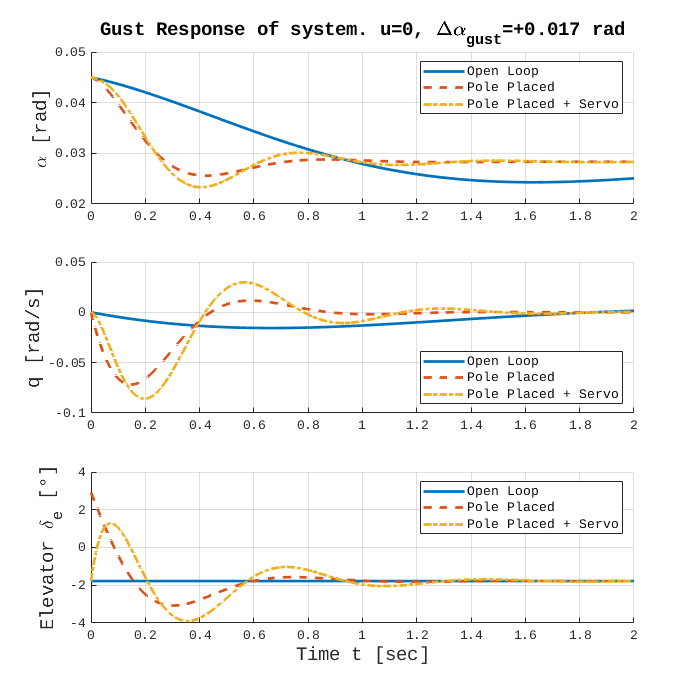

Ch6_q_Command: 'Verify' Gibson 1 (DB)...


DB_over_qss = 0.0409

DB_over_qss_veri = 0.0405

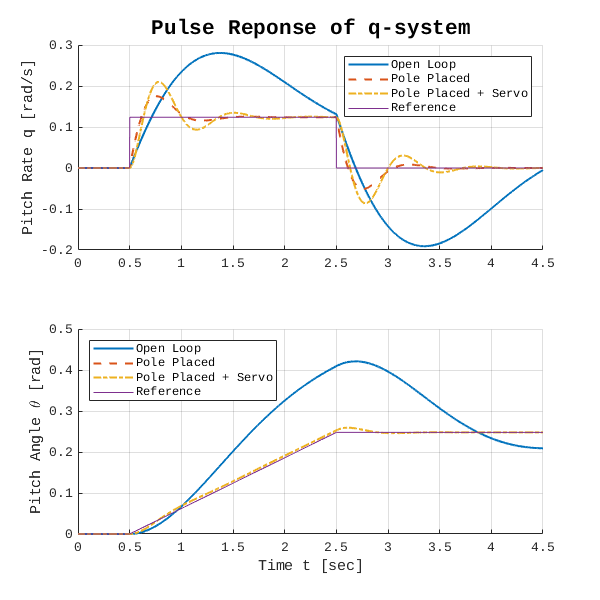

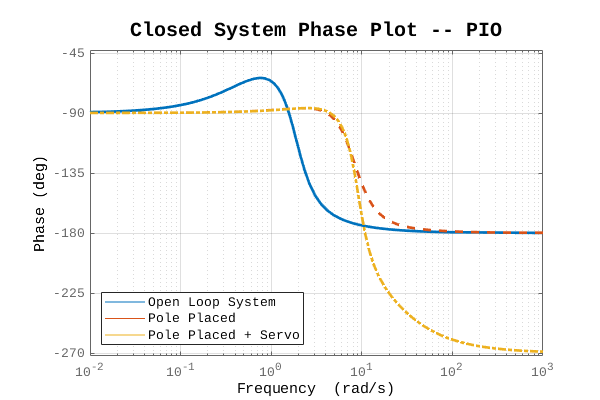

Ch6_q_Command: Handling Characteristics after Pole/Zero placment


q_ctl_table = 7×3 table
                             OpenLoop    NoServo     ServoInLoop
                             ________    ________    ___________

    CAP                      0.19012      0.39226      0.48071  
    zeta                     0.42909          0.5      0.31278  
    Gibson 1 - qm/qs          2.2633       1.4125       1.6942  
    Gibson 1 - DB/qs          0.0845     0.040918     0.039845  
    Gibson 2 - XOver             NaN          NaN       1.7284  
    Gibson 2 - Phase Rate        NaN          NaN      -82.201  
    Gust max el              -1.7797       -3.075      -3.8909  


clearvars -except show_plots fc zeros_el2an_sweep char_tab
close("all")

% note: To obtain the last line in Table 7; re-run Ch6_q_Command.m, but
% uncomment line 55
run Ch6_q_Command.m

## Chapter 7 Landing Controller pitch

clearvars -except show_plots fc zeros_el2an_sweep char_tab q_ctl_table BasicCharTab
close("all")

% definitely check out Landing.slx!

new_section("main: Landing Controller (Chapter 7)")




    main: Landing Controller (Chapter 7)
    ------------------------------------




% note: it's hard to show with a script; but the method of tuning the
% controllers/couplers of the Landing.slx was with SISOTool! 
% 1. we assigned inputs and outputs in the Simulink model
% 2. changed the Simulink model to an open-loop version of the respective loop
% 3. then linearized 
% 4. then opened SISOTool
% 5. save the result in Outputs/Ch7_Landing/Landing_controllers
% 
% Check out the cell "design control loops" of the Ch7_Landing.m script:
run Ch7_Landing.m

Ch7_Landing: Checking if SS matrices exist...OK
PlacePoles.m: Verify same implementation PLacePoles.m and q_loop.slx...

ss_sim_sys_el2q_tf =
 
   -0.0066682 (s+4.712)
  ----------------------
  (s^2 + 10.68s + 39.48)
 
Continuous-time zero/pole/gain model.


H_pp_filt_q =
 
   -0.0066682 (s+4.712)
  ----------------------
  (s^2 + 10.68s + 39.48)
 
Continuous-time zero/pole/gain model.



Ch6_q_Command: 'Verify' Gibson 1 (DB)...


DB_over_qss = -0.0579

DB_over_qss_veri = -0.0584

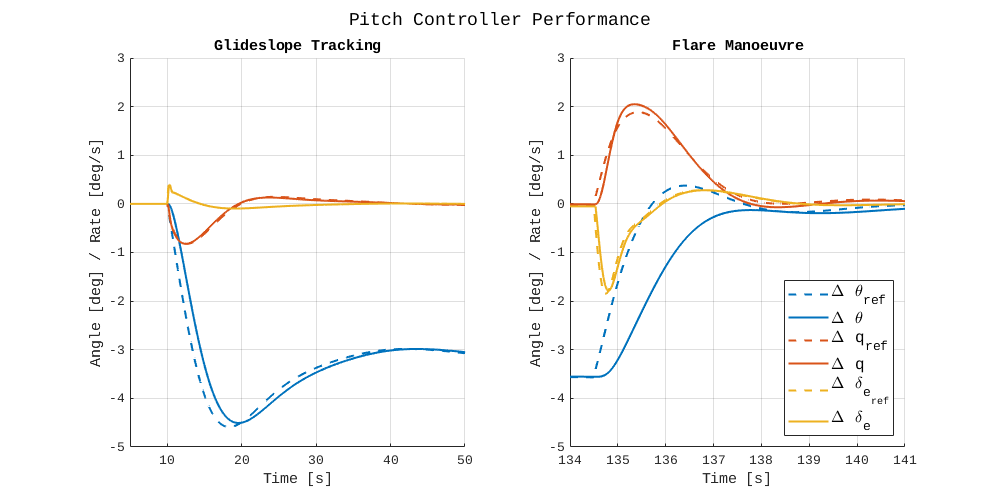

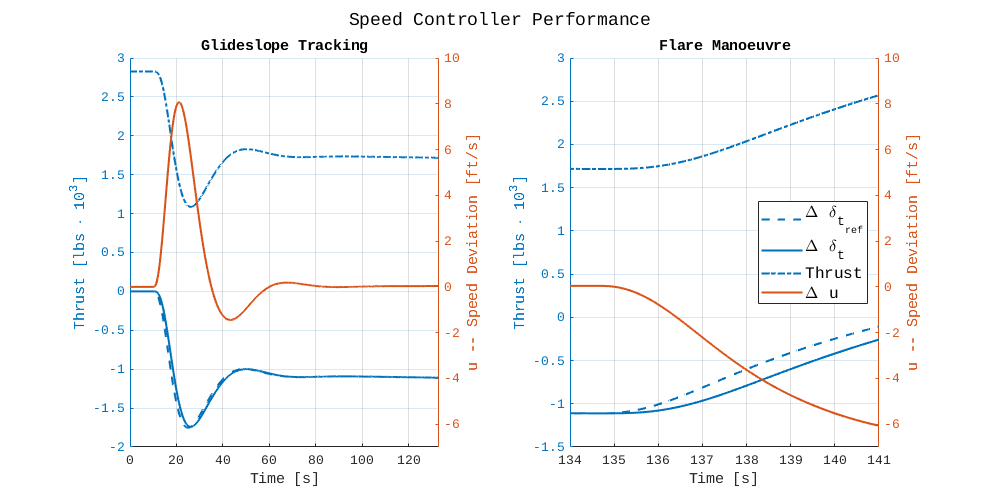

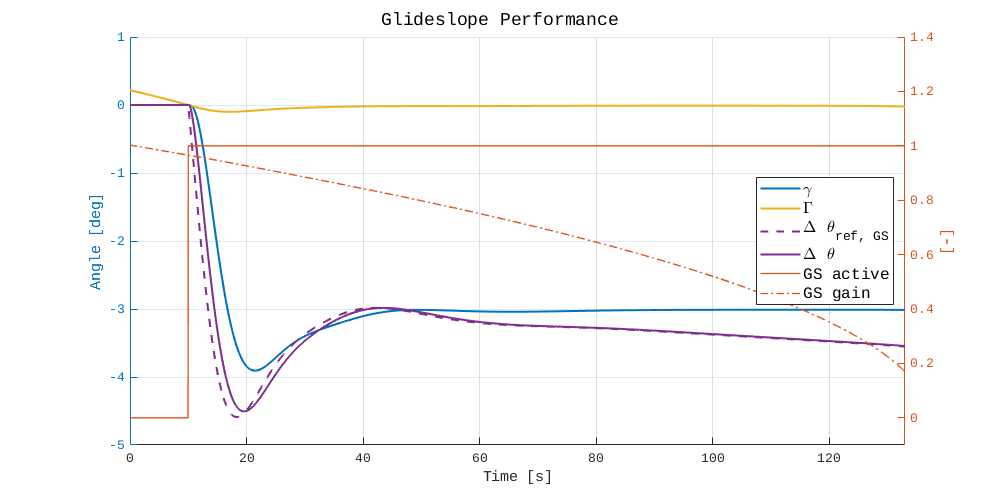

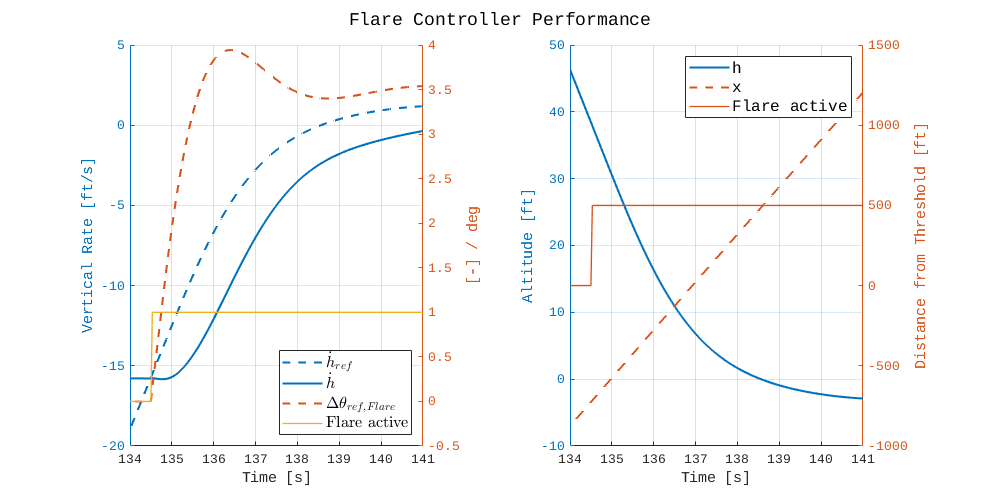

close('all')
run Ch7_LandingPlotting.m

## Cleanup

clearvars -except show_plots fc zeros_el2an_sweep char_tab q_ctl_table BasicCharTab
close("all")

function new_section(headline)

    % our Group's standard flight condition: 30000ft, 900ft/s
    fprintf("\n")
    fprintf("\n")
    fprintf("\n")
    disp("    " + headline)
    disp("    " + repmat('-', 1, length(char(headline))))
    fprintf("\n")

end